fs=48000;
chirp_duration = 8;
t = 0:1/fs:chirp_duration-1/fs;
f0 = 50;       % Starting frequency in Hz
f1 = 16000;      % Ending frequency in Hz
chirp_signal = chirp(t, f0, chirp_duration, f1);

% a=readmatrix("buffer1_0101_001811.csv");
% recorded_chirp_50s = a(:, 1);
% audiowrite('daq_chirp1245am_buffer1.wav',recorded_chirp_50s,fs)

% 
% [c,lags] = xcorr(recorded_chirp_50s.', chirp_signal);
% plot(lags,c)

% b=recorded_chirp_50s(1:15*fs);
% [c_t,lags_t] = xcorr(b.', chirp_signal);

% [maxValue, index] = max(c_t);
% starting_index=lags_t(index);

## for taking data from multiple files


data_sum=zeros(8*fs,1);
recorded_files={'chirp50s0130am_0101_004313.csv','chirp50s1230am_0101_002618.csv','chirp50s1245am_0101_003146_0115am.csv'};
str = convertCharsToStrings(recorded_files);
num_record=length(str);
for i=1:num_record
    a=readmatrix(str(i));
    recorded_chirp_50s = a(:, 1);
    % for finding the starting point of first chirp
    b=recorded_chirp_50s(1:15*fs);
    [c,lags] = xcorr(b.', chirp_signal);
    [maxValue, index] = max(c);
    starting_index=lags(index);
    start_0=starting_index;
    end_8s=starting_index+8*fs;
    for j=1:4
        data1=recorded_chirp_50s(start_0:end_8s-1);
        data_sum=data_sum+data1;
        start_0=end_8s+2*fs;
        end_8s=start_0+8*fs;
    end
end

Nfft = 131072; % No. of points in FFT is 2^13
frequencies = (-Nfft/2:Nfft/2-1)*(fs/Nfft);


% data_sum=zeros(8*fs,1);
% start_0=starting_index;
% end_8s=starting_index+8*fs;
% for i=1:4
%     data1=recorded_chirp_50s(start_0:end_8s-1);
%     data_sum=data_sum+data1;
%     start_0=end_8s+2*fs;
%     end_8s=start_0+8*fs;
% end



data_average=data_sum/4*num_record;
output_jw=fftshift(fft(data_average,Nfft));

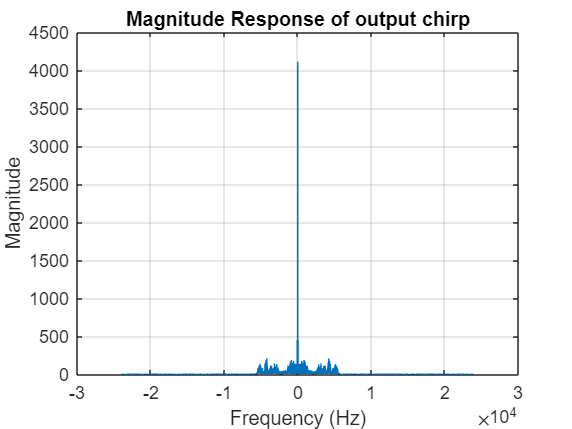

% Plot the magnitude response of output 
plot(frequencies, abs(output_jw));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Magnitude Response of output chirp');
grid on;

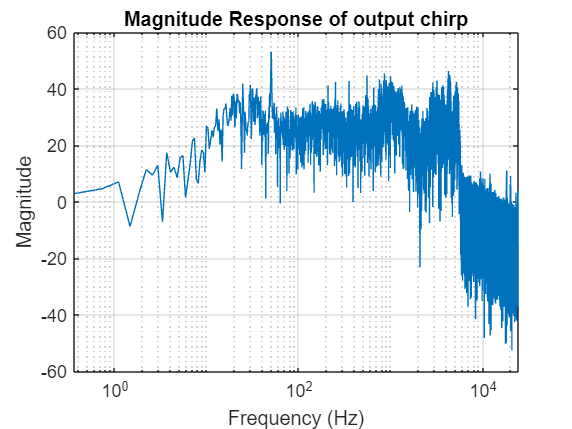

semilogx(frequencies,20*log10(abs(output_jw)));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Magnitude Response of output chirp');
grid on;

% magnitude reponse of channel on log scale
chirp_jw=fftshift(fft(chirp_signal,Nfft));

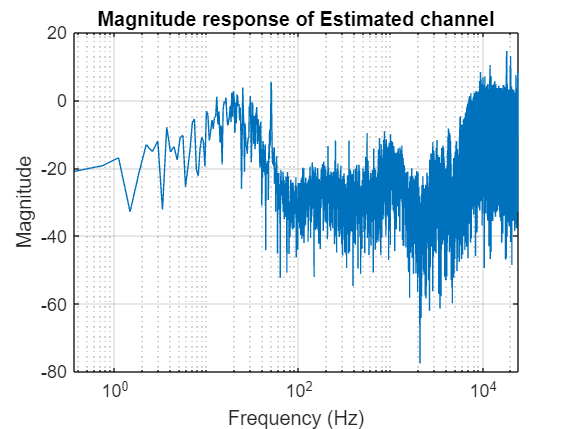

H_jw=output_jw./(chirp_jw.'+1e-5);
% plot(frequencies,abs(H_jw));
semilogx(frequencies,20*log10(abs(H_jw)));
title('Magnitude response of Estimated channel');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;

% phase response of channel
H_jw_phase=angle(H_jw);

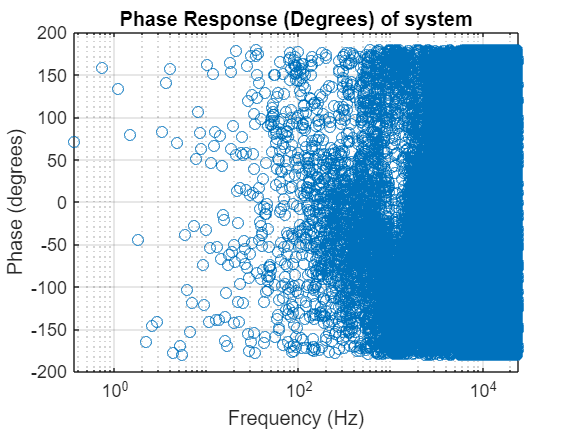

H_phase_degrees = rad2deg(H_jw_phase);
semilogx(frequencies, H_phase_degrees,'o');
title('Phase Response (Degrees) of system');
xlabel('Frequency (Hz)');
ylabel('Phase (degrees)');
grid on;